%% load
M = readmatrix('integ.txt','FileType','text','NumHeaderLines',1);
t = M(:,1); outp = M(:,2); outn = M(:,3);
inp = M(:,4); inn = M(:,5);
vd  = outp - outn;          % output diff
vcm = (outp + outn)/2;      % output CM

%% clock timing
fs = 2.048e6; T = 1/fs;
t2_start = 246.14e-9;  t2_pw = 238e-9;
N = floor((t(end) - t2_start)/T);
k = 0:N-1;
t_end = t2_start + t2_pw - 2e-9 + k*T;     % phi2 끝 직전 샘플 시점

%% sampled output (end of each phi2)
vd_s  = interp1(t, vd,  t_end);
vcm_s = interp1(t, vcm, t_end);
step  = diff([0 vd_s]);                    % cycle별 변화량

%% expected step (D alternating, input 0)
Cd_Ci = 2.1/7;  Vdac = 0.6;
step_ideal = 2*Cd_Ci*Vdac;                 % 0.36 V
fprintf('step mean |.| = %.5f V (ideal %.3f, err %.2f %%)\n', ...
    mean(abs(step)), step_ideal, (mean(abs(step))/step_ideal-1)*100);

step mean |.| = 0.35693 V (ideal 0.360, err -0.85 %)



%% settling : phi2 마지막 40ns 동안 변화량
win = 40e-9;
settle = zeros(1,N);
for i = 1:N
    idx = t > t_end(i)-win & t <= t_end(i);
    settle(i) = max(vd(idx)) - min(vd(idx));
end
LSB16 = 1.2/2^16                          % 차동 FS 1.2V 기준

LSB16 = 1.8311e-05

fprintf('max settling residue = %.3g V (%.2f LSB16)\n', max(settle), max(settle)/LSB16);

max settling residue = 1.03e-06 V (0.06 LSB16)


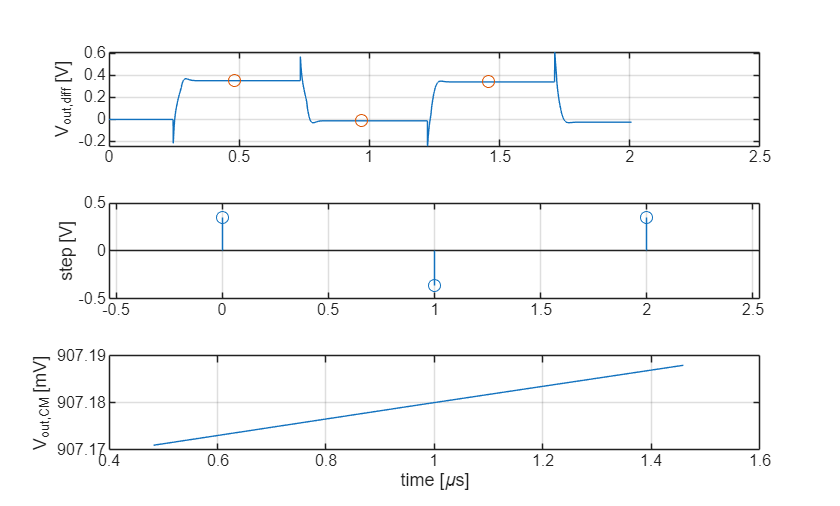


%% plot
figure;
subplot(3,1,1); plot(t*1e6, vd); hold on; plot(t_end*1e6, vd_s, 'o');
ylabel('V_{out,diff} [V]'); grid on;
subplot(3,1,2); stem(k, step); ylabel('step [V]'); grid on;
subplot(3,1,3); plot(t_end*1e6, vcm_s*1e3); ylabel('V_{out,CM} [mV]');
xlabel('time [\mus]'); grid on;